# P4. Trajectory Tracking

Vehicle Control Systems

Degree in Electronics, Robotics and Mechatronics Engineering

University of Malaga

Created by: David Rodríguez Martínez

Last updated: 11 November 2026

### Introduction and objectives

This file contains the coursework instructions and code blocks to complete. The vehicle plant and longitudinal controller (ACC > Fx) have already been designed. This exercise introduces a simple Pure Pursuit lateral controller producing a steering angle. It is the first combined longitudinal/lateral closed-loop exercise.

Reminder: what is Pure Pursuit?

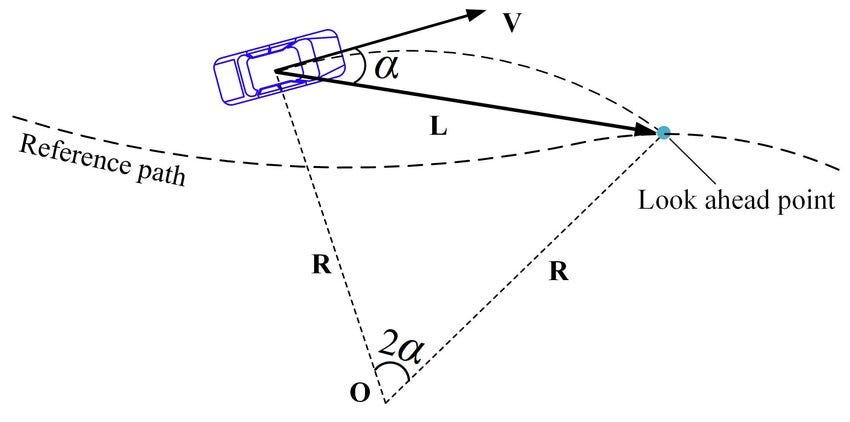

*A simple geometric path-tracking algorithm used in robotics and autonomous driving.*

- *The algorithm selects a target lookahead point on the desired path, at a lookahead distance L_d ahead of the car.*$$

- *It calculates the circular arc (alpha) that starts at the car's current heading and passes through that point.*$$

- *The controller outputs the steering angle needed to follow that arc.*

- *At each control cycle, vehicle position is updated and the target point advances along the trajectory: the vehicle pursues the path.*

Reference: Coulter, R. C. (1992). Implementation of the pure pursuit path tracking algorithm (No. CMURITR9201).

For Formula Student Driverless, the Autocross cones define the reference trajectory.

The lateral-controller interface is:

% [delta, mem] = controlLateral(est, path, p, mem)

- `est = estimated vehicle state (position, heading, speed, etc.)`

- path = reference trajectory: a list of centreline points [x y]

- ref = desired references: cruise speed (ref.v_set) and lead-vehicle information (ref.lead_X, ref.lead_vx)

- p = parameters (mass, resistance, limits, gains, dt, etc.)

- mem = controller memory: internal state retained between steps, including integrators and previous commands.

After completing this exercise, you should be able to:

- Implement a geometric Pure Pursuit lateral controller that follows a reference trajectory.

- Integrate lateral steering control with longitudinal speed control.

- Measure cross-track error and identify where and why Pure Pursuit begins to fail.

#### What you will implement

A) The Pure Pursuit method as part of controlLateral.

### Vehicle, controller and road parameters

p = struct(); % explicit definition (not required)

p.m    = 230;      % mass [kg]
p.g    = 9.81;     % gravity [m/s^2]
p.rho  = 1.225;    % air density [kg/m^3]
p.Cd   = 1.0;      % aerodynamic coefficient
p.Af   = 1.1;      % frontal area [m^2]
p.fr  = 0.022;    % rolling-resistance coefficient
p.Fx_drive_max = 2500;   % maximum driving force [N]
p.Fx_brake_max = 5000;   % maximum braking force [N]
p.theta        = 0;      % road inclination [rad]

% adhesion per axle
p.mu_t = 1.5; 
p.mu_d = 0.95*p.mu_t; 

% vehicle lateral dynamics
p.ld = 0.765; % CG to front axle [m]; FS Driverless wheelbase must exceed 1.525 m
p.lt = 0.765; % CG to rear axle [m]
p.Iz = 130; % yaw inertia [kg*m^2]
p.Cad = 35000; % front cornering stiffness [N/rad]
p.Cat = 50000; % rear cornering stiffness [N/rad]

% ACC law
p.d0  = 6;       % minimum standstill gap [m]
p.h   = 1.5;     % time headway [s]
p.Kv  = 1.5;     % speed-mode gain [1/s]
p.Kg  = 0.4;     % gap-mode gain [1/s^2*m]
p.Kd  = 1.0;     % relative-speed gain [1/s]
p.jerk_max = 30; % acceleration-rate (jerk) limit [m/s^3]

% simple speed control
p.Kp_v = 800;
p.Ki_v = 200;

% Pure Pursuit
p.Ld0 = 2.0; % base lookahead [m]
p.kLd = 0.3; % speed-dependent lookahead
p.delta_max = 0.5;

% simulation parameters
p.v_set = 14; % desired speed [m/s]
p.dt = 0.002; % integration step


### Vehicle model

Given the current vehicle state, applied driving force and steering angle, calculate where the vehicle will be at the next time step.

% Longitudinal and lateral dynamics integration

function z_next = pasoDinamico(z, u, p, dt)
    Fx = u(1);
    delta = u(2);
    X = z(1); Y =z(2); psi = z(3);
    vx = z(4); vy = z(5); r = z(6);
    L = p.ld + p.lt;
    vx_c = max(vx, 1.0); % corrected speed to avoid division by zero in slip angles
    
    % slip angles and lateral forces
    alpha_d = delta - (vy + p.ld*r)/vx_c;
    alpha_t = - (vy - p.lt*r)/vx_c;
    Fyd = p.Cad*alpha_d; % linear tyre model
    Fyt = p.Cat*alpha_t; % linear tyre model

    % Adhesion limit (mu*Fz budget per axle)
    Fzd = p.m*p.g*p.lt/L;  
    Fzt = p.m*p.g*p.ld/L;
    % Front-axle saturation
    Fyd = max(min(Fyd, p.mu_d*Fzd), -p.mu_d*Fzd); 
    % Rear-axle saturation
    Fyt = max(min(Fyt, p.mu_t*Fzt), -p.mu_t*Fzt);
    % Longitudinal grip
    Fx_max = p.mu_d*Fzd + p.mu_t*Fzt;
    Fx = max(min(Fx, Fx_max), - Fx_max);

    % Longitudinal dynamics
    Ra = 0.5*p.rho*p.Cd*p.Af*vx^2;      % aerodynamic resistance
    Rr  = p.fr*p.m*p.g*cos(p.theta);    % rolling resistance opposing travel
    Rg = p.m*p.g*sin(p.theta);          % gravity, zero in E1
    
    % Equations of motion (chassis CG)
    ax_l    = (Fx - Ra - sign(vx)*Rr- Rg) / p.m; % L1 equation of motion
    ax = ax_l + vy*r; % L1 plus centripetal coupling from turning the velocity vector
    ay = (Fyd + Fyt)/p.m - vx*r;
    dr  = (p.ld*Fyd - p.lt*Fyt)/p.Iz;

    % Integration and global kinematics
    vx_next  = max(vx + ax*dt, 0);
    vy_next  = vy + ay*dt;
    r_next   = r  + dr*dt;
    X_next   = X + (vx*cos(psi) - vy*sin(psi))*dt;
    Y_next   = Y + (vx*sin(psi) + vy*cos(psi))*dt;
    psi_next = psi + r*dt;
    z_next = [X_next; Y_next; psi_next; vx_next; vy_next; r_next];
end

### Speed controller

Define a simple speed controller based on P1, and the final-interface Pure Pursuit controlLateral. P3's longitudinal controller could be used but is not required for this exercise.

% Simple speed control
function [Fx, e_int] = controlVelocidadSimple(v_ref, vx, e_int, dt, p)
    e = v_ref - vx;  e_int = e_int + e*dt;
    Fx = p.Kp_v*e + p.Ki_v*e_int;
    Fx = min(max(Fx, -p.Fx_brake_max), p.Fx_drive_max);
end

% Lateral control

function [delta, mem] = controlLateral(est, path, p, mem)
    x = est.X; y = est.Y; psi = est.psi; vx = est.vx;
    L = p.ld + p.lt;

L4 — error de seguimiento (cross-track):


    Ld = p.Ld0 + p.kLd*max(vx, 0);

   medio = 0.65 m | máximo = 6.26 m


   vuelta completada en 15.5 s (v_set = 50 km/h)


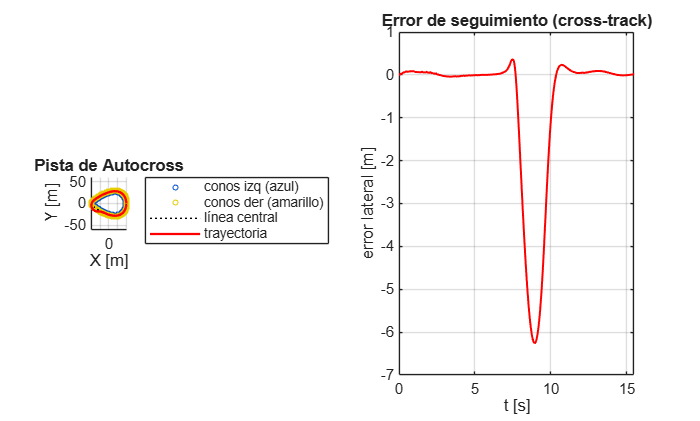

    % Extract the target point where the lookahead distance intersects
    % the reference path.
    [tx, ty, mem.idx] = buscarPuntoAdelante(path, x, y, Ld, mem.idx);

    % calculate geometry

    alpha = atan2(ty-y,tx-x) -psi;
    alpha = atan2(sin(alpha), cos(alpha)); % normalize steering to [-pi,pi]
    delta = atan2(2*L*sin(alpha),Ld);

    delta = max(min(delta, p.delta_max), -p.delta_max);
end




% Helper that finds the first lookahead point at a
% distance Ld
function [tx, ty, idx] = buscarPuntoAdelante(path, x, y, Ld, idx)
% Return the target point and updated index.
    N = size(path,1);
    
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2; % after deviation, re-anchor the index to the nearest point
    [~, icerca] = min(d2);
    idx = icerca;

    for step = 0:N % advance along the path until reaching Ld
        j = mod(idx-1+step,N) +1;
        if hypot(path(j,1)-x, path(j,2)-y) >= Ld
            tx = path(j,1);  ty = path(j,2);  idx = j;  return;
        end
    end
    j = mod(idx-1+round(N/10), N) + 1; % if no point is far enough, use the furthest available point ahead
    tx = path(j,1);  ty = path(j,2);  idx = j;
end

### Test-track geometry

Simulate Autocross: one lap of a circuit.

% Autocross track
ancho = 3.0; 
[centro, cono_izq, cono_der] = generarPista(ancho);
p.path = centro; 

function hist = simularE3(z0, p, centro, dt) % Autocross
    z = z0;  N = size(centro,1);
    mem_lat.idx = 1;  e_int = 0;
    Nmax = 60000;                         
    t=zeros(1,Nmax); X=zeros(1,Nmax); Y=zeros(1,Nmax); PSI=zeros(1,Nmax);
    VX=zeros(1,Nmax); ECT=zeros(1,Nmax);
    vuelta_ini = false;  k_fin = Nmax;
    for k = 1:Nmax
        est.X=z(1); est.Y=z(2); est.psi=z(3); est.vx=z(4); est.vy=z(5); est.r=z(6);
        % Lateral control (Pure Pursuit)
        [delta, mem_lat] = controlLateral(est, centro, p, mem_lat);
        % Longitudinal control (target speed, simple PI)
        [Fx, e_int] = controlVelocidadSimple(p.v_set, z(4), e_int, dt, p);
        % Plant (L2 dynamic bicycle model)
        z = pasoDinamico(z, [Fx; delta], p, dt);
        % Logging and lateral error
        t(k)=(k-1)*dt; X(k)=z(1); Y(k)=z(2); PSI(k)=z(3); VX(k)=z(4);
        ECT(k) = errorLateral(z(1), z(2), centro);
        % Lap complete? Move away from the start, then return
        d_ini = hypot(z(1)-centro(1,1), z(2)-centro(1,2));
        if ~vuelta_ini && d_ini > 10, vuelta_ini = true; end
        if vuelta_ini && d_ini < 2 && k > 100, k_fin = k; break; end
    end
    f=1:k_fin;
    hist.t=t(f); hist.X=X(f); hist.Y=Y(f); hist.psi=PSI(f); hist.vx=VX(f); hist.ect=ECT(f);
end

function e_ct = errorLateral(x, y, path) % positive e means left of the reference path
    d2 = (path(:,1)-x).^2 + (path(:,2)-y).^2;
    [~,i] = min(d2);  j = mod(i, size(path,1)) + 1;
    tang = atan2(path(j,2)-path(i,2), path(j,1)-path(i,1));
    dx = x-path(i,1); dy = y-path(i,2);
    e_ct = -sin(tang)*dx + cos(tang)*dy;
end

function [centro, cono_izq, cono_der] = generarPista(ancho)
    N = 240;  s = linspace(0, 2*pi, N+1)';  s(end) = [];
    a = 40; b = 26;
    xc = a*cos(s);
    yc = b*sin(s) + 6*sin(2*s);               
    centro = [xc, yc];
    dx = gradient(xc);  dy = gradient(yc);
    Ln = hypot(dx,dy);  nx = -dy./Ln;  ny = dx./Ln;
    cono_izq = [xc + (ancho/2)*nx, yc + (ancho/2)*ny];
    cono_der = [xc - (ancho/2)*nx, yc - (ancho/2)*ny];
end

### Simulation

dt = p.dt;
% Initial state: first track point, facing the second
dir0 = atan2(centro(2,2)-centro(1,2), centro(2,1)-centro(1,1));

z0 = [centro(1,1); centro(1,2); dir0; p.v_set*0.5; 0; 0]; % initial state

hist = simularE3(z0, p, centro, dt); % Autocross

### Results

Expected response: the vehicle follows the track centreline with a small lateral error, typically tens of centimetres at this speed. It may cut tighter corners depending on lookahead distance, a typical Pure Pursuit behaviour.

fprintf('L4 — cross-track error:\n');
fprintf('   mean = %.2f m | maximum = %.2f m\n', mean(abs(hist.ect)), max(abs(hist.ect)));
fprintf('   lap completed in %.1f s (v_set = %.0f km/h)\n', hist.t(end), p.v_set*3.6);

% Plots
figure('Name','L4 · Pure Pursuit','Color','w');
subplot(1,2,1); hold on; axis equal; grid on;
  plot(cono_izq(:,1), cono_izq(:,2), 'o','Color',[0 .3 .8],'MarkerSize',3);
  plot(cono_der(:,1), cono_der(:,2), 'o','Color',[.9 .8 0],'MarkerSize',3);
  plot(centro(:,1), centro(:,2), 'k:','LineWidth',0.8);
  plot(hist.X, hist.Y, 'r-','LineWidth',1.4);
  legend('left cones (blue)','right cones (yellow)','centreline','trayectoria','Location','bestoutside');
  title('Autocross track'); xlabel('X [m]'); ylabel('Y [m]');
subplot(1,2,2);
  plot(hist.t, hist.ect,'r','LineWidth',1.2); grid on;
  ylabel('lateral error [m]'); xlabel('t [s]'); title('Cross-track error');

Increase speed: what maximum speed keeps cross-track error below 1 m? At what speed does the car leave the circuit?

Vary lookahead distance and/or the speed gain. Where is the best lookahead point?